# Computational Analysis of RNA Polymerase Ribozyme Activity and Phylogeny

## Data Loading

Polymerase ribozyme data was obtained from Tjhung *et al.* 2020 in GEO database entry [GSE142114](https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE142114). Sequences were obtained from [Appendix, Table S4](https://www.pnas.org/content/pnas/suppl/2020/01/21/1914282117.DCSupplemental/pnas.1914282117.sapp.pdf) of the same study.

In the raw sequencing data, 1739398 reads were obtained for sequencing of Pol 24-3 transcripts. 162136 reads were obtained from sequencing of Pol 38-6 transcripts.

% Sequences
pol24_3 = ['AGUCAUUGCCGCACGAAAGACAAAUCUGCCCUCAGAGCUUGAGAACAUCUUCGGAUGC' ...
    'AGAGGAGGCAGCCUUCGGUGGAACGAUCGUGCCACCGUUCUCAACACGUACCCGAACGAAAAAGA' ...
    'CCUGACAAAAAGGCGUUGUUAGACACGCCCAGGUGCCAUACCCAACACAUGGCUGAC'];

pol38_6 = ['AGUCAUUGCCGCACAAAGACAAAUCUCCCCUCAGAGCUUGAGAACAUCUACGGAUGCAG' ...
    'AGGAGGGGGCCUUCGGUGGAUCAAUUGUGCACCACCGUUCUCAACACGUACCCGAACAUAAAAAGA' ...
    'CCUGACAAAAAGGCGAUGUUAGACACGCACAGGUGCCAUACCCAACACAUGGCUGAC'];

hammerhead = 'CACUCCACACGACGUACUGAUGAGGCCGAAAGGCCGAAAAGCG';

ligase = ['GGAAAAGACAAAUCUGCCCUCAGAGCUUGAGAACAUCUUCGGAUGCAGGGGAGGCAGCC' ...
    'CCCGGUGGCUUUAACGCCAACGUUCUCAACAAUAGUGA'];

% Class 1 ligase fragments
f1 = 'GGAUGCUACAUGGGAAAAGACAAAUCUGCCCUCAGAGCUUGAGAACAUCUUCGACAUUCGUGUC';
f2 = 'GGUCGAAUGAUCGGAUGCAGGGGAGGCAGCCCCCGGUGGCGCGCAAUAGUUGGU';
f3 = 'GGCAUAUCCAGCGCGCCAACGUUCUCAACAAUAGUGACGUACGAAUCGU';


% Polymerase transcript RNA seq read data
data24_3 = readtable("GSE142114_NGS_Hammerhead_Length_Filtered.xlsx",'Sheet','24-3 raw data');


data38_6 = readtable("GSE142114_NGS_Hammerhead_Length_Filtered.xlsx",'Sheet','38-6 raw data');

## Polymerase Processivity

Examining processivity of 38-6 and 24-3 ribozymes, where processivity is defined as the number of nucleotides the polymerase can add before terminating polymerization.

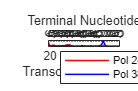

% Processivity data obtained using the processivity.m function:
[proc24_3,lengths_24] = processivity(data24_3);
[proc38_6,lengths_38] = processivity(data38_6);

% Add "Zero read" fields to 38-6 table
proc_38ends = proc24_3(end-3:end,:);
proc_38ends.Length = zeros(4,1);
proc38_6 = vertcat(proc38_6,proc_38ends);

% Combine to one table
proc24_3.Properties.VariableNames = {'Pol_24-3','Sequence'};
proc38_6.Properties.VariableNames = {'Pol_38-6','Sequence'};
proc_all = horzcat(proc38_6(:,1),proc24_3);

% Plot Processivity over sequence length and sequence identity:
seqlength = lengths_24;
sequencefull = proc_all.Sequence{end};
seq = dna2rna(sequencefull(seqlength));


figure; hold on;
    % Plot over transcript length
t = tiledlayout(1,1);
ax1 = axes(t);
plot(ax1,seqlength, proc_all.("Pol_24-3"),'-r','LineWidth',1);hold on;
plot(ax1,seqlength, proc_all.("Pol_38-6"),'-b','LineWidth',1);hold on;
xlim([19,63])
xlabel('Transcript Length (nt)')
ax2 = axes(t);

    % plot over sequence
plot(ax2,seqlength, proc_all.("Pol_24-3"),'-r','LineWidth',1);hold on;
plot(ax2,seqlength, proc_all.("Pol_38-6"),'-b','LineWidth',1);hold on;
ax2.Color = 'none';
ax2.XAxisLocation = 'top';
xlabel('Terminal Nucleotide')
xlim([19,63])
xticks(seqlength)
xticklabels(seq')

    % Set y-axis and plot size.
ax1.YAxis.Exponent = 0;
ax2.YAxis.Exponent = 0;
ylabel('Fraction of Total Sequencing Reads')

legend('Pol 24-3', 'Pol 38-6','Location', 'northwest')
x0=10;
y0=10;
width=3000;
height=2000;
set(gcf,'position',[x0,y0,width,height]);
hold off;

## Polymerase Fidelity

Examining fidelity of 38-6 and 24-3 ribozymes, where fidelity is the ability of the polymerase to accurately copy the template when polymerizing the transcript. This is interrogated by examining mismatches, insertions, and deletions in the sequence.

First, we filter for the most enriched reads (The top 97% of reads). This is done to prevent muddying of the data due to the normalization process (i.e. if there are insufficient reads to get an accurate estimation of errors).:

% Filtering using a 0.03 cutoff for fraction of total reads:

proc24_3x = addvars(proc24_3,seqlength,'Before',  'Pol_24-3');
proc24_3x = sortrows(proc24_3x,"Pol_24-3",'descend');
proc38_6x = addvars(proc38_6,seqlength,'Before', 'Pol_38-6');
proc38_6x = sortrows(proc38_6x,"Pol_38-6",'descend');
proc_allx = addvars(proc_all,seqlength,'Before',  'Pol_38-6');

filt24_3 = proc24_3x(proc24_3x.("Pol_24-3") > 0.03,1);
filt38_6 = proc38_6x(proc38_6x.("Pol_38-6") > 0.03,1);
filter = unique(vertcat(filt38_6,filt24_3)).seqlength;



Now, the filtered read data is processed to obtain error rate data. We first plot the transcript-length dependent data:

% Using the fidelity.m function:

[pos24_3,length24_3] = fidelity(data24_3,filter);
[pos38_6,length38_6] = fidelity(data38_6,filter);

lengths = length24_3.Length;
positions = pos24_3.Position;


 We first plot the transcript-length dependent data:

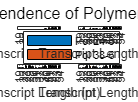

% Plot Length-Dependent Fidelity
figure; hold on;
subplot(2,2,1); % Deletions
bar([length24_3.Deletions,length38_6.Deletions]);
set(gca, 'xticklabel', lengths); xlabel('Transcript Length (nt)');
ylabel('Fractions of Reads with Deletions');
legend('Pol 24-3', 'Pol 38-6','Location', 'northwest')


subplot(2,2,2); % Insertions
p = bar([length24_3.Insertions,length38_6.Insertions]);
set(gca, 'xticklabel', lengths); xlabel('Transcript Length (nt)');
ylabel('Fractions of Reads with Insertions'); ax = gca;

subplot(2,2,3); % Mismatches
bar([length24_3.Mismatches,length38_6.Mismatches]);
set(gca, 'xticklabel', lengths); xlabel('Transcript Length (nt)');
ylabel('Fractions of Reads with Mismatches');

subplot(2,2,4); % ErrorRate
bar([length24_3.ErrorRate,length38_6.ErrorRate]);
set(gca, 'xticklabel', lengths); xlabel('Transcript Length (nt)');
ylabel('Fractions of Reads with Polymerization Error');

sgtitle('Length-Dependence of Polymerase Fidelity')

hold off;

Next the position-dependent fidelity data is plotted:

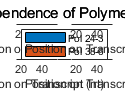


% Plot Position-Dependent Fidelity
figure; hold on;
subplot(2,2,1); % Deletions
bar(positions,[pos24_3.Deletions,pos38_6.Deletions]);
xlabel('Position on Transcript (nt)'); xlim([15 55]);
ylabel('Fractions of Reads with Deletions');
legend('Pol 24-3', 'Pol 38-6','Location', 'northwest')


subplot(2,2,2); % Insertions
p = bar(positions,[pos24_3.Insertions,pos38_6.Insertions]);
xlabel('Position on Transcript (nt)'); xlim([15 55]);
ylabel('Fractions of Reads with Insertions'); ax = gca;

subplot(2,2,3); % Mismatches
bar(positions,[pos24_3.Mismatches,pos38_6.Mismatches]);
xlabel('Position on Transcript (nt)'); xlim([15 55]);
ylabel('Fractions of Reads with Mismatches');

subplot(2,2,4); % ErrorRate
bar(positions,[pos24_3.ErrorRate,pos38_6.ErrorRate]);
xlabel('Position on Transcript (nt)'); xlim([15 55]);
ylabel('Fractions of Reads with Polymerization Error');

sgtitle('Position-Dependence of Polymerase Fidelity')

hold off;

## Sequence Alignments

% BLASTn search of Pol 38-6 and Pol 24-3 ribozymes against the nucleotide 
% collection database.
%% Remove comments on blastncbi() function calls to generate blast data.
% [blast38_6,w1] = blastncbi(pol38_6,'blastn');
% [blast24_3,w2] = blastncbi(pol24_3,'blastn');

bdat38_6 = getblast(blast38_6,'WaitTime',w1);

Blast results are not available yet. Please wait ...


bdat24_3 = getblast(blast24_3,'WaitTime',w1);

Blast results are not available yet. Please wait ...



% BLASTn search of Class 1 Ligase ribozyme against the nucleotide collection
% database.
% [blast_ligase,w3] = blastncbi(ligase,'blastn');

bdat_ligase = getblast(blast_ligase,'WaitTime',w3);

Blast results are not available yet. Please wait ...
